# 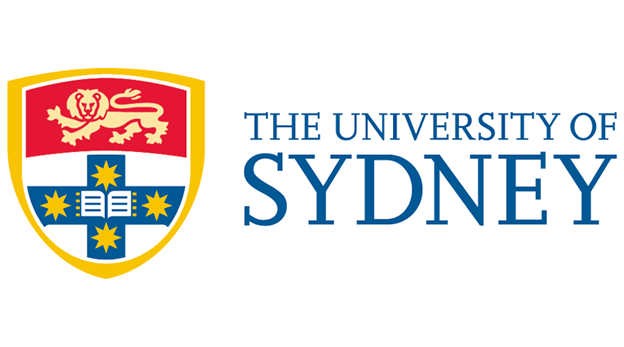

# ELEC5305 Acoustics, Speech and Signal Processing (Lab Report 1) 

Author: Jiahao Xu 

SID: 530332675 

Date: 31/08/2025

## Objective

The purpose of this report is to demonstrate basic audio signal processing in MATLAB through the analysis of both speech and music signals. The work includes operations in the time domain and frequency domain, the synthesis of a bell sound using decaying sinusoids, and the extraction of short-time features such as energy, zero-crossing rate, and spectral measures. A comparison between speech and music is carried out to show how these features change with signal type. Finally, narrowband and wideband short-time Fourier transforms are applied to speech signals to highlight the trade-off between frequency resolution and time resolution.

## Background / Introduction

Audio signals contain useful information in both the time and frequency domains. Speech often has strong energy below 4 kHz, while music usually shows wider frequency content. Several measures are used to describe signals. Short-time energy is related to loudness, while zero-crossing rate shows how often the signal changes sign and is sometimes linked with noisiness. Spectral centroid and spectral bandwidth describe the distribution of spectral energy, and spectral flux and rolloff capture changes and cumulative energy in the spectrum. Bell sounds can be modelled as sums of decaying sine waves, where each component has its own frequency, amplitude, and decay rate. Over time, the signal fades in a natural way. Speech is a non-stationary signal. Its frequency content changes as time passes. A standard Fourier transform cannot describe this well. The short-time Fourier transform (STFT) addresses this issue. It divides the signal into short windows.A longer window gives better frequency detail but poorer time resolution, while a shorter window provides better time localisation but worse frequency detail.

## Methodology / Implementation

The work was divided into five main parts. In Part 1, music and speech signals were loaded, converted to mono, segmented into 15-second portions, and plotted in the time domain. In Part 2, time and frequency analysis was performed on the speech signal using the fast Fourier transform (FFT). The one-sided spectrum was produced to show how energy is distributed over frequency. The discrete Fourier transform can be expressed as：


$$$$
X(k) = \sum_{n=0}^{N-1} x(n) e^{-j 2 \pi kn/N}
$$$$


In Part 3, a bell sound was synthesised by summing decaying sinusoids of the form


$$$$
y(t) = A e^{-t/\tau} \sin(2 \pi f t)
$$$$


with parameters controlling frequency, amplitude, and decay rate. Part 4 focused on feature extraction, where short-time energy, zero-crossing rate, spectral centroid, spectral bandwidth, spectral flux, and spectral rolloff were computed for both speech and music. Framing and windowing with a Hamming window were applied to capture time-varying properties. Finally, in Part 5, the short-time Fourier transform was used to compare narrowband and wideband spectrograms of speech. Different window lengths were applied to highlight the trade-off between frequency resolution and time resolution.

To clearly demonstrate the signal processing workflow, a pipeline diagram was created:

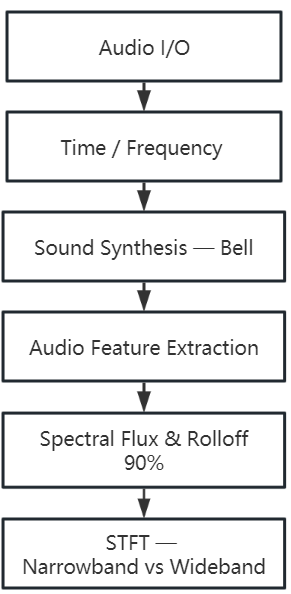

%% CONFIG
clc; close all;

paths.music  = 'C:\Users\12465\Downloads\Toolbox\Toolbox\Sounds\Pianomusic.mp3';
paths.speech = 'C:\Users\12465\Downloads\Toolbox\Toolbox\Sounds\Testvoice.wav';

% common analysis settings 
defaults.fsU        = 22050;   
defaults.segT       = 10;      
defaults.viewT      = 10;      
defaults.stftViewT  = 6;       

% PDF-safe figure sizing 
figPos = [0.12 0.12 0.70 0.70]; 

% quick sanity check
assert(isfile(paths.music),  'Music file not found: %s', paths.music);
assert(isfile(paths.speech), 'Speech file not found: %s', paths.speech);


%% Part 1: Audio I/O
[x, fs] = loadMono(paths.music);
durSec  = numel(x)/fs;
fprintf('File: %s\nfs = %d Hz | duration = %.2f s | mono\n', paths.music, fs, durSec);

File: C:\Users\12465\Downloads\Toolbox\Toolbox\Sounds\Pianomusic.mp3
fs = 44100 Hz | duration = 111.01 s | mono


Tseg = min(15, floor(durSec));
Nseg = max(1, floor(Tseg*fs));
xSeg = x(1:Nseg);

[outPath, ~] = fileparts(paths.music);
segFile = fullfile(outPath, 'part1_first15s_music.wav');
audiowrite(segFile, xSeg, fs);
fprintf('Saved segment (0–%d s) -> %s\n', Tseg, segFile);

Saved segment (0–15 s) -> C:\Users\12465\Downloads\Toolbox\Toolbox\Sounds\part1_first15s_music.wav


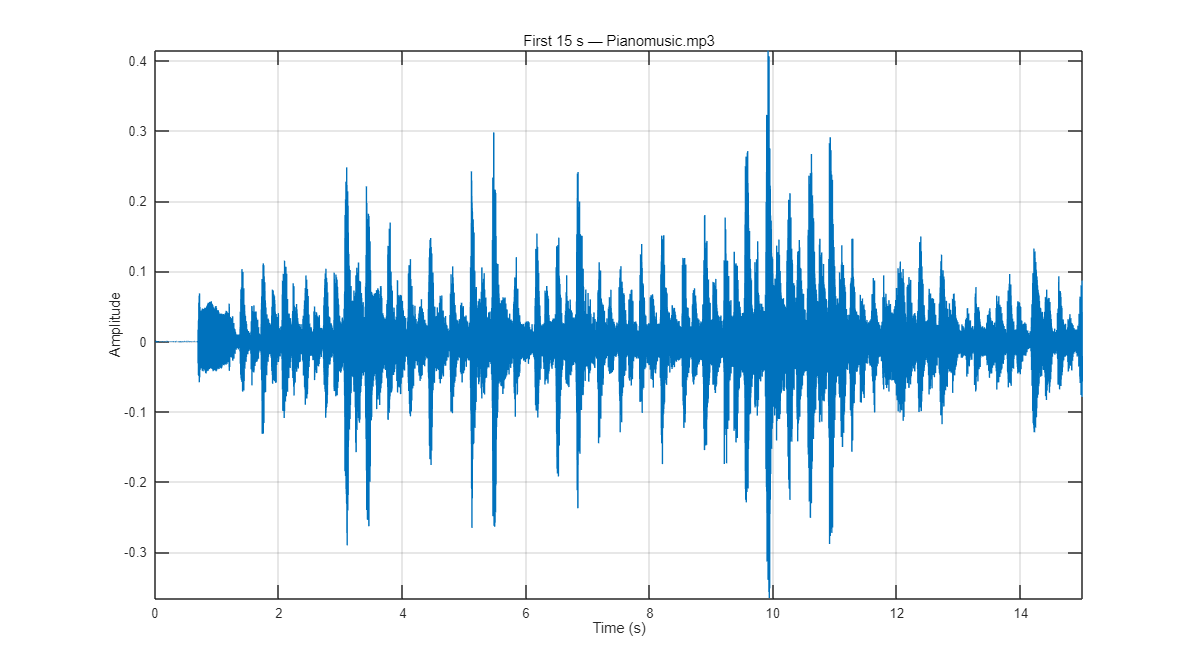

t = (0:numel(xSeg)-1)/fs;
figure('Name','Part 1: First 15 s Waveform','Color','w','Units','normalized','Position',figPos); 
plot(t, xSeg); grid on;
xlabel('Time (s)'); ylabel('Amplitude');
title(sprintf('First %.0f s — %s', Tseg, stripFile(paths.music)));
axis tight manual


peak = max(abs(xSeg));
if peak > 0.98
    warning('Segment peak=%.3f close to 1 (possible clipping).', peak);
end

%% Part 2: Time / Frequency (Speech)
[x, fs] = loadMono(paths.speech);
durSec  = numel(x)/fs;
fprintf('Speech file: %s\nfs = %d Hz | duration = %.2f s | mono\n', paths.speech, fs, durSec);

Speech file: C:\Users\12465\Downloads\Toolbox\Toolbox\Sounds\Testvoice.wav
fs = 48000 Hz | duration = 5.86 s | mono


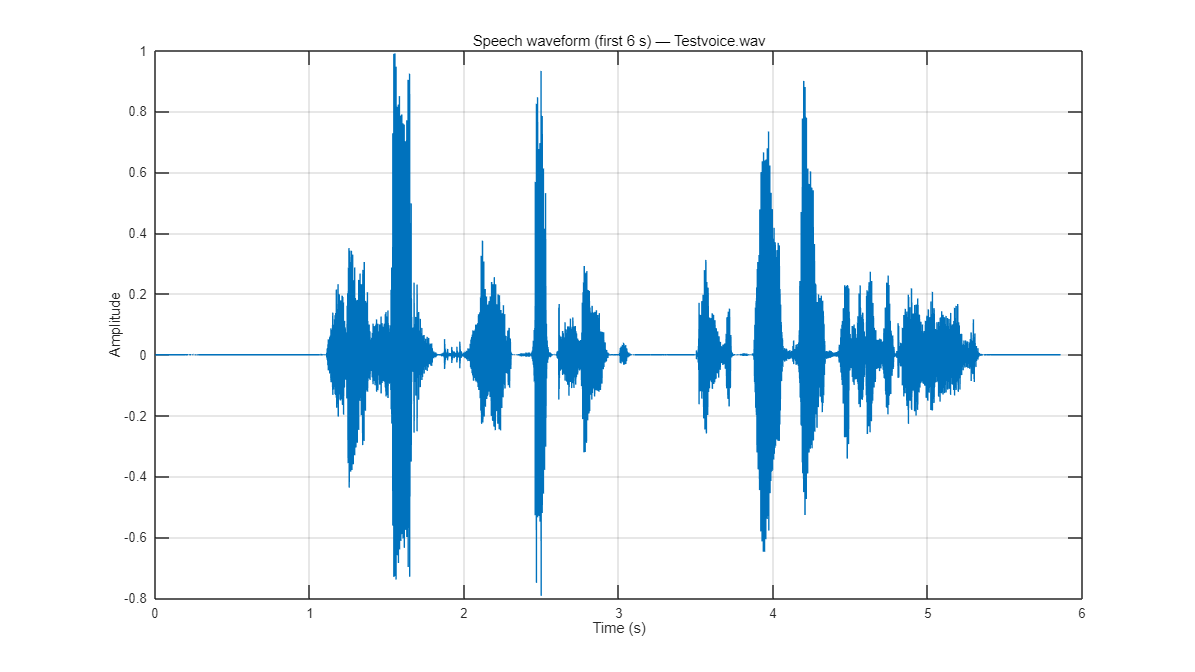

Tview = min(defaults.viewT, durSec);
Nview = max(1, floor(Tview*fs));
xv = x(1:Nview);
tv = (0:Nview-1)/fs;

figure('Name','Part 2: Speech - Time Domain','Color','w','Units','normalized','Position',figPos);  % // CHANGED
plot(tv, xv); grid on;
xlabel('Time (s)'); ylabel('Amplitude');
title(sprintf('Speech waveform (first %.0f s) — %s', Tview, stripFile(paths.speech)));

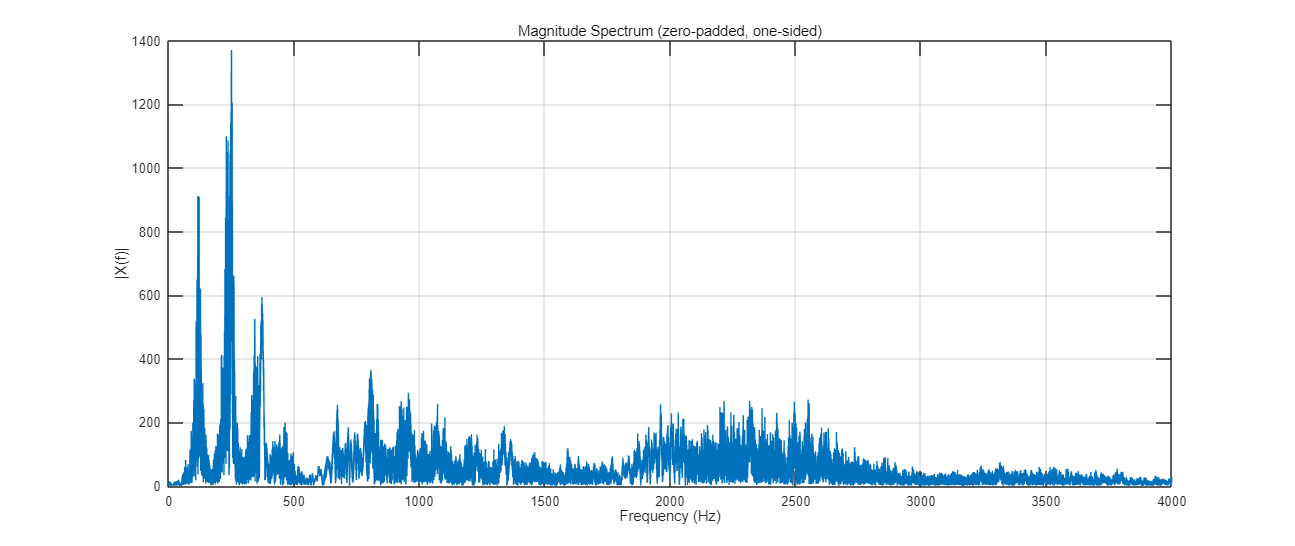

N    = numel(xv);
Nfft = 2^nextpow2(N); 
X    = fft(xv, Nfft);
Mag  = abs(X(1:Nfft/2+1));
fpos = (0:Nfft/2)*(fs/Nfft);

figure('Name','Part 2: Speech - Magnitude Spectrum (one-sided)', ...
       'Color','w','Units','normalized','Position',[0.1 0.1 0.8 0.6]);
plot(fpos, Mag); grid on;
xlabel('Frequency (Hz)'); ylabel('|X(f)|');
title('Magnitude Spectrum (zero-padded, one-sided)');

xlim([0 min(fs/2, 4000)]);   

Ppos = (Mag.^2); Ppos = Ppos / sum(Ppos + eps);
Pcum = cumsum(Ppos); idx95 = find(Pcum >= 0.95, 1, 'first');
if ~isempty(idx95)
    f95 = fpos(idx95);
    fprintf('~95%% cumulative power lies within 0–%.0f Hz.\n', max(f95,0));
end

~95% cumulative power lies within 0–2538 Hz.


%%Part 3: Sound Synthesis — Bell (decaying sinusoids)
fsSyn = 4000;  T = 30;  tSyn = (0:1/fsSyn:T).';
freq = 1.5*[40 80 96 120 160 200 214 240 320 427 533];
tau  = [75 23.1 23.1 8.7 4.3 2.0 5.2 7.2 6.1 4.3 2.9];
Amp  = [3 5 8 2 4 4 9 4 4 2 1];

bell = zeros(size(tSyn));
for k = 1:numel(freq)
    bell = bell + Amp(k).*exp(-tSyn./tau(k)).*sin(2*pi*freq(k).*tSyn);
end
bell = bell / max(abs(bell) + eps);
audiowrite('part3_bell.wav', bell, fsSyn);
disp('Saved: part3_bell.wav');

Saved: part3_bell.wav


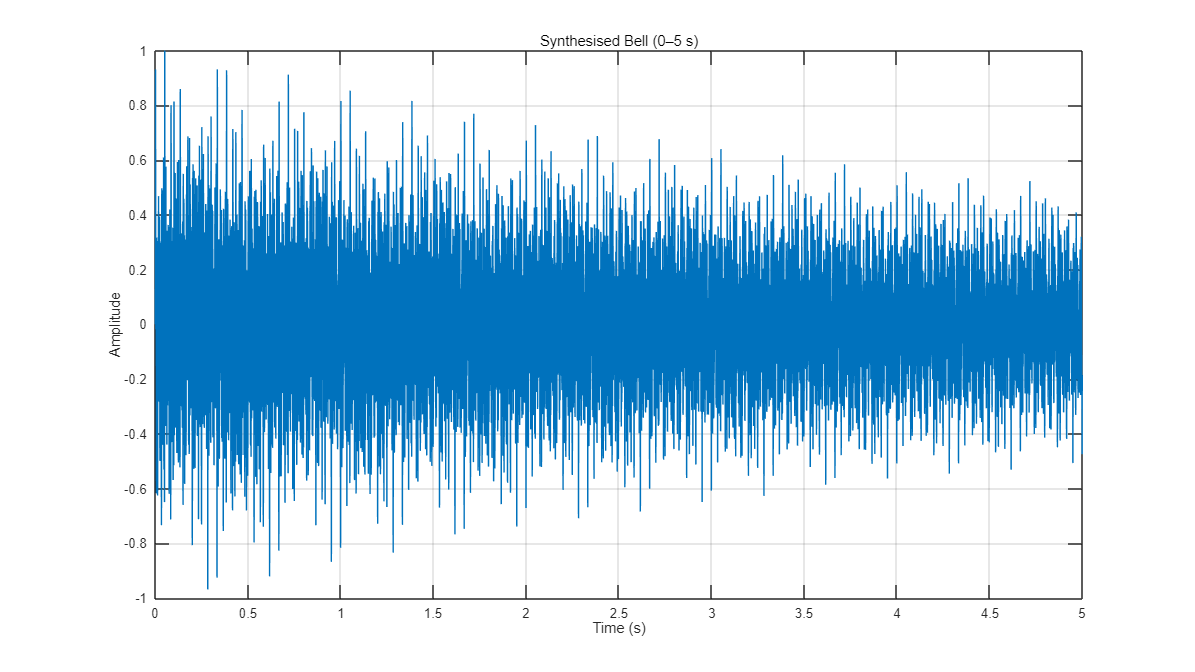

Ns = min(numel(tSyn), round(5*fsSyn));
figure('Name','Part 3: Bell waveform (0–5 s)','Color','w','Units','normalized','Position',figPos);  % // CHANGED
plot(tSyn(1:Ns), bell(1:Ns)); grid on;
xlabel('Time (s)'); ylabel('Amplitude'); title('Synthesised Bell (0–5 s)');

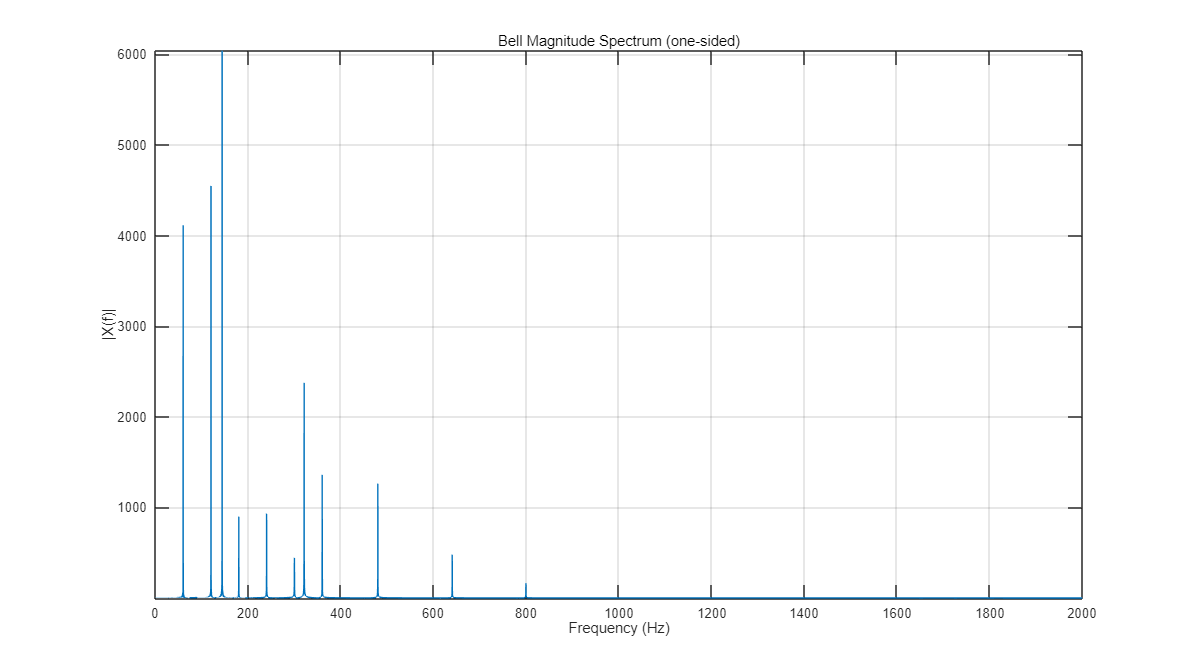

Nfft = 2^nextpow2(numel(bell));
B    = fft(bell, Nfft);
Mag  = abs(B(1:Nfft/2+1));
fpos = (0:Nfft/2)*(fsSyn/Nfft);

figure('Name','Part 3: Bell magnitude spectrum','Color','w','Units','normalized','Position',figPos);  % // CHANGED
plot(fpos, Mag); grid on; xlim([0 1500]);
xlabel('Frequency (Hz)'); ylabel('|X(f)|');
title('Bell Magnitude Spectrum (one-sided)');
axis tight manual

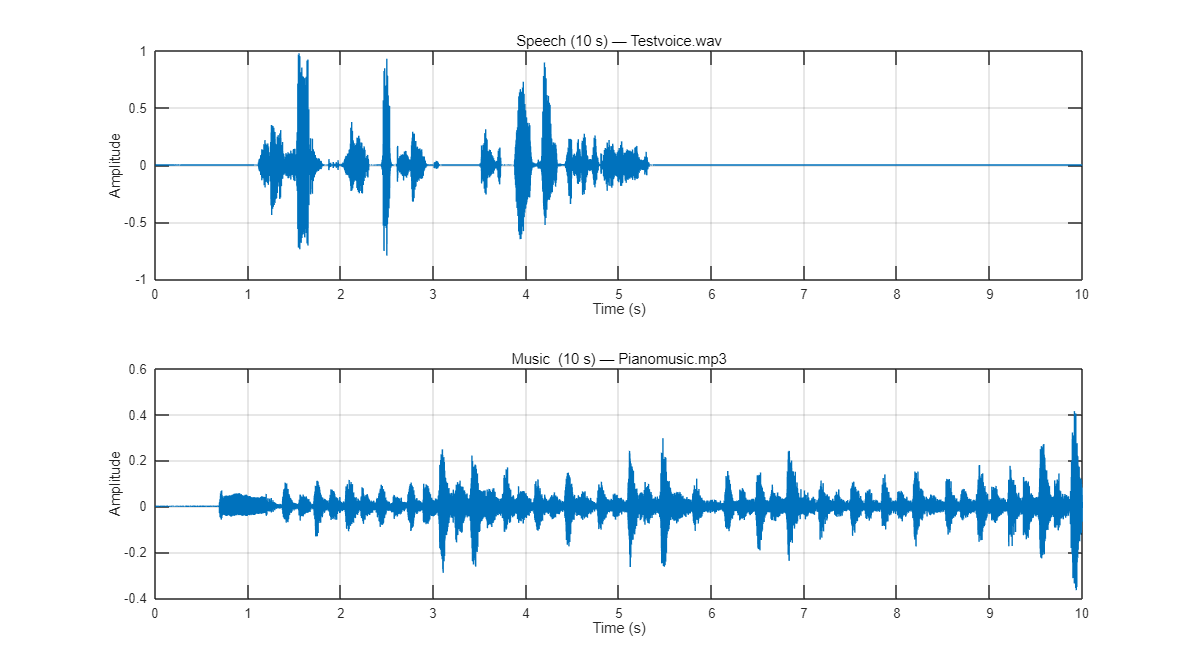

%%Part 4: Audio Feature Extraction — Speech vs Music
fsU  = defaults.fsU;  segT = defaults.segT;
wlen = round(0.025*fsU); hop = round(0.010*fsU);
win  = hamming(wlen,'periodic');

[xs, fss] = loadMono(paths.speech);
[xm, fsm] = loadMono(paths.music);

xs = takeSeconds(xs, fss, segT); xs = resample(xs, fsU, fss);
xm = takeSeconds(xm, fsm, segT); xm = resample(xm, fsU, fsm);

frames_s = buffer(xs, wlen, wlen-hop, 'nodelay') .* win;
frames_m = buffer(xm, wlen, wlen-hop, 'nodelay') .* win;
tFeat    = (((0:size(frames_s,2)-1)*hop) + wlen/2)/fsU;

[ste_s, zcr_s, sc_s, sbw_s] = featuresFromFrames(frames_s, fsU);
[ste_m, zcr_m, sc_m, sbw_m] = featuresFromFrames(frames_m, fsU);

figure('Name','Part 4: Waveforms (10 s)','Color','w','Units','normalized','Position',figPos);
subplot(2,1,1);
plot((0:numel(xs)-1)/fsU, xs); grid on;
xlabel('Time (s)'); ylabel('Amplitude');
title(['Speech (10 s) — ' stripFile(paths.speech)]);
subplot(2,1,2);
plot((0:numel(xm)-1)/fsU, xm); grid on;
xlabel('Time (s)'); ylabel('Amplitude');
title(['Music  (10 s) — ' stripFile(paths.music)]);

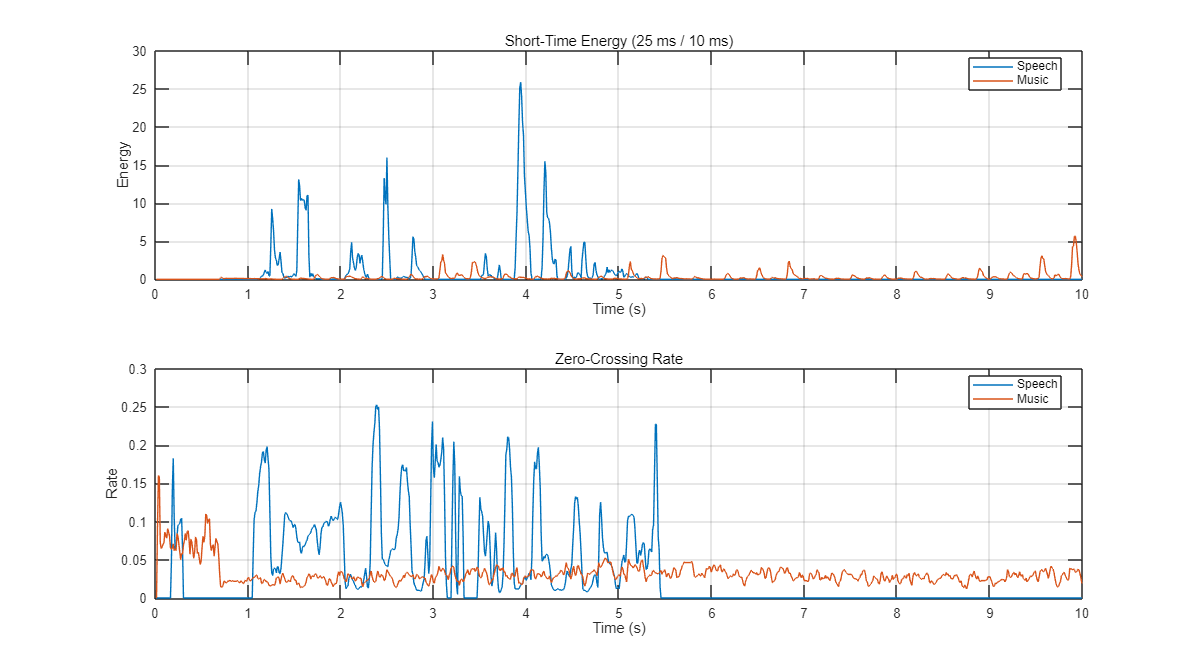

figure('Name','Part 4: STE & ZCR','Color','w','Units','normalized','Position',figPos); 
subplot(2,1,1);
plot(tFeat, ste_s); hold on; plot(tFeat, ste_m); grid on;
legend('Speech','Music','Location','best');
xlabel('Time (s)'); ylabel('Energy'); title('Short-Time Energy (25 ms / 10 ms)');
subplot(2,1,2);
plot(tFeat, zcr_s); hold on; plot(tFeat, zcr_m); grid on;
legend('Speech','Music','Location','best');
xlabel('Time (s)'); ylabel('Rate'); title('Zero-Crossing Rate');

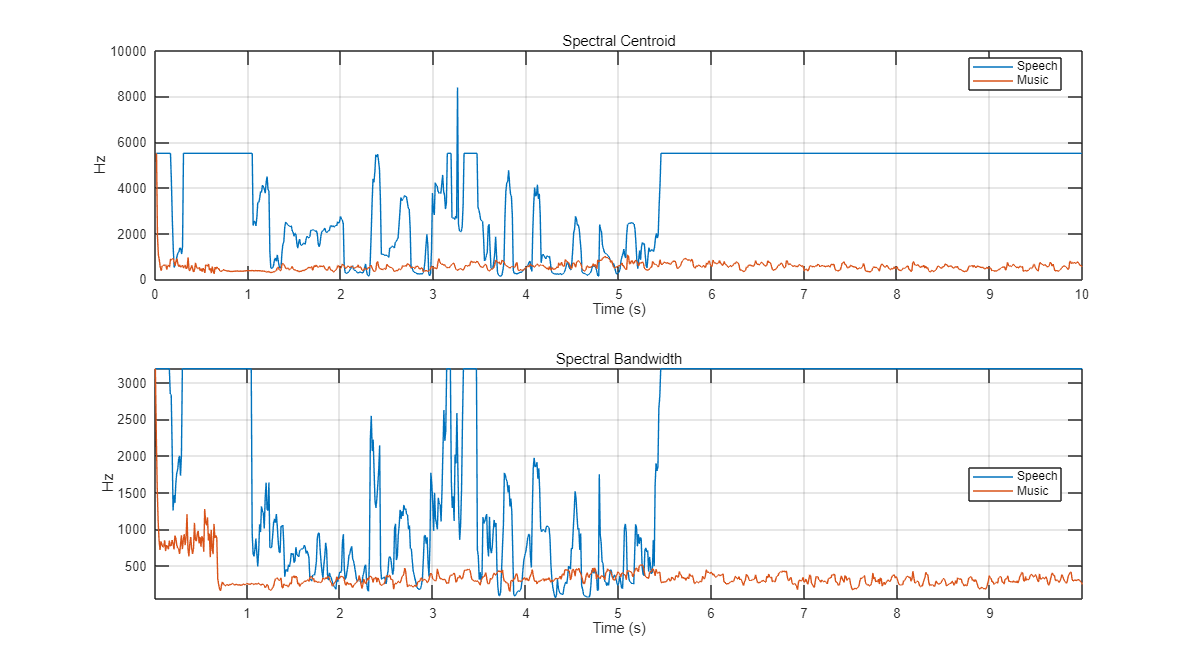

figure('Name','Part 4: Spectral Features','Color','w','Units','normalized','Position',figPos);  
subplot(2,1,1);
plot(tFeat, sc_s); hold on; plot(tFeat, sc_m); grid on;
legend('Speech','Music','Location','best');
xlabel('Time (s)'); ylabel('Hz'); title('Spectral Centroid');
subplot(2,1,2);
plot(tFeat, sbw_s); hold on; plot(tFeat, sbw_m); grid on;
legend('Speech','Music','Location','best');
xlabel('Time (s)'); ylabel('Hz'); title('Spectral Bandwidth');
axis tight manual

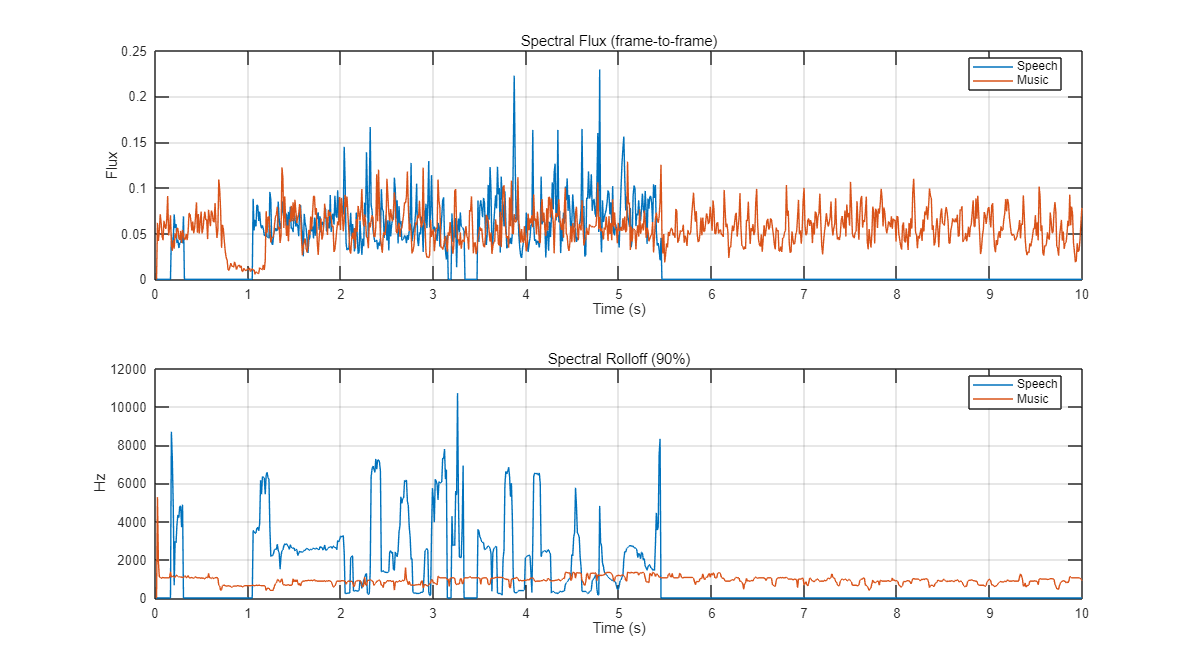

% Spectral Flux & Rolloff 90%
NfftF = 2^nextpow2(wlen);
% Speech
MAGs = abs(fft(frames_s, NfftF, 1)); MAGs = MAGs(1:NfftF/2+1,:);
Ns   = sum(MAGs,1)+eps;               Ns = MAGs ./ Ns;           
flux_s = [0, sqrt(sum((diff(Ns,1,2)).^2,1))];                     
Pcum_s = cumsum(MAGs.^2,1); Ptot_s = Pcum_s(end,:);               
thr_s  = 0.90*Ptot_s;
[~,rollIdx_s] = arrayfun(@(k) min(abs(Pcum_s(:,k)-thr_s(k))), 1:size(MAGs,2));
fgrid = (0:NfftF/2)*(fsU/NfftF);
roll_s = fgrid(rollIdx_s);

% Music
MAGm = abs(fft(frames_m, NfftF, 1)); MAGm = MAGm(1:NfftF/2+1,:);
Nm   = sum(MAGm,1)+eps;               Nm = MAGm ./ Nm;
flux_m = [0, sqrt(sum((diff(Nm,1,2)).^2,1))];
Pcum_m = cumsum(MAGm.^2,1); Ptot_m = Pcum_m(end,:);
thr_m  = 0.90*Ptot_m;
[~,rollIdx_m] = arrayfun(@(k) min(abs(Pcum_m(:,k)-thr_m(k))), 1:size(MAGm,2));
roll_m = fgrid(rollIdx_m);

figure('Name','Part 4: Spectral Flux & Rolloff','Color','w','Units','normalized','Position',figPos);  % // NEW
subplot(2,1,1);
plot(tFeat, flux_s); hold on; plot(tFeat, flux_m); grid on;
legend('Speech','Music','Location','best');
xlabel('Time (s)'); ylabel('Flux'); title('Spectral Flux (frame-to-frame)');
subplot(2,1,2);
plot(tFeat, roll_s); hold on; plot(tFeat, roll_m); grid on;
legend('Speech','Music','Location','best');
xlabel('Time (s)'); ylabel('Hz'); title('Spectral Rolloff (90%)');

fprintf('Flux mean  | Speech: %.4f  Music: %.4f\n', mean(flux_s,'omitnan'), mean(flux_m,'omitnan'));

Flux mean  | Speech: 0.0288  Music: 0.0560


fprintf('Rolloff90%%| Speech: %.1f Hz  Music: %.1f Hz\n', mean(roll_s,'omitnan'), mean(roll_m,'omitnan'));

Rolloff90%| Speech: 1143.0 Hz  Music: 929.5 Hz


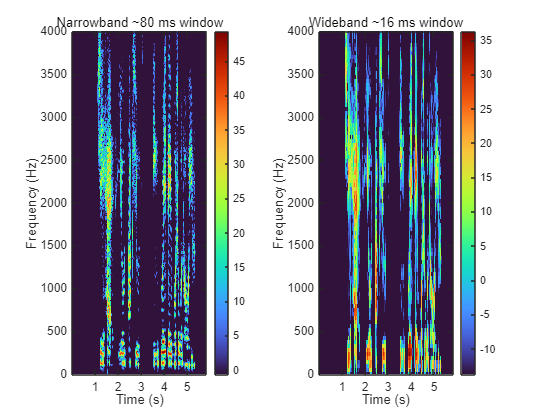

%% Part 5: STFT — Narrowband vs Wideband (Speech) 
[x, fs] = loadMono(paths.speech);

Tview = min(defaults.stftViewT, numel(x)/fs);
x = x(1:round(Tview*fs));

hop_nb = round(0.020*fs);  winLen_nb = 4*hop_nb;
hop_wb = round(0.004*fs);  winLen_wb = 4*hop_wb;
win_nb = hann(winLen_nb, 'periodic');  olap_nb = winLen_nb - hop_nb;
win_wb = hann(winLen_wb, 'periodic');  olap_wb = winLen_wb - hop_wb;

[Snb, fnb, tnb] = spectrogram(x, win_nb, olap_nb, [], fs, 'yaxis');
[Swb, fwb, twb] = spectrogram(x, win_wb, olap_wb, [], fs, 'yaxis');

dynRange = 50;  
Snb_dB = mag2db(abs(Snb) + 1e-12); Snb_dB = max(Snb_dB, max(Snb_dB(:))-dynRange);
Swb_dB = mag2db(abs(Swb) + 1e-12); Swb_dB = max(Swb_dB, max(Swb_dB(:))-dynRange);

figure('Name','Part 5: STFT — Narrowband vs Wideband','Color','w');

ax1 = subplot(1,2,1);
imagesc(ax1, tnb, fnb, Snb_dB); set(ax1,'YDir','normal'); colorbar(ax1);
xlabel(ax1,'Time (s)'); ylabel(ax1,'Frequency (Hz)');
title(ax1, sprintf('Narrowband ~%.0f ms window', 1000*winLen_nb/fs));
ylim(ax1,[0 4000]);                       

ax2 = subplot(1,2,2);
imagesc(ax2, twb, fwb, Swb_dB); set(ax2,'YDir','normal'); colorbar(ax2);
xlabel(ax2,'Time (s)'); ylabel(ax2,'Frequency (Hz)');
title(ax2, sprintf('Wideband ~%.0f ms window', 1000*winLen_wb/fs));
ylim(ax2,[0 4000]);                       
colormap turbo;

%% Helper functions
function [x, fs] = loadMono(filePath)
assert(isfile(filePath), 'File not found: %s', filePath);
[x, fs] = audioread(filePath);
if size(x,2) > 1, x = x(:,1); end
end

function name = stripFile(pathStr)
[~, name, ext] = fileparts(pathStr);
name = [name ext];
end

function xN = takeSeconds(x, fs, seconds)
N = round(seconds*fs);
if numel(x) >= N, xN = x(1:N);
else, xN = zeros(N,1); xN(1:numel(x)) = x; end
end

function [ste, zcr, sc, sbw] = featuresFromFrames(frames, fs)
ste = sum(frames.^2,1);
sgn = sign(frames); sgn(sgn==0) = 1;
zcr = sum(abs(diff(sgn,1,1))>0, 1) / (2*(size(frames,1)-1));
Nfft = 2^nextpow2(size(frames,1));
F    = (0:Nfft-1)*(fs/Nfft);
MAG  = abs(fft(frames, Nfft, 1));
MAG  = MAG(1:Nfft/2+1,:);   Fh = F(1:Nfft/2+1).';
P    = (MAG+1e-12).^2;      sumP = sum(P,1);
sc   = sum(Fh.*P,1)./sumP;
varF = sum(((Fh - sc).^2).*P,1)./sumP;
sbw  = sqrt(varF);
end

## Discussion

The results showed clear differences between speech and music in both time and frequency analysis. Speech signals exhibited strong low-frequency components, with energy concentrated below 4 kHz, while music displayed wider and richer spectral content. The synthesis of the bell sound confirmed that complex sounds can be built by combining simple sinusoidal components, and the decaying envelope reproduced a natural fading tone. Feature extraction provided insight into how signals can be characterised numerically. Speech generally had higher variation in short-time energy and zero-crossing rate due to silence gaps and phoneme changes, while music signals were smoother and more continuous. Spectral centroid and bandwidth also reflected this difference, with music spanning a wider range of frequencies. The additional measures of spectral flux and rolloff confirmed that speech tends to show sharper spectral transitions. In the STFT results, the narrowband spectrogram gave finer frequency detail but blurred time events, while the wideband spectrogram showed sharper time events but less precise frequency detail. This trade-off demonstrated why window size selection is important when analysing non-stationary signals such as speech.

## Conclusion

This report presented a complete workflow for basic audio signal processing in MATLAB. The tasks included audio input and output, spectral analysis, sound synthesis, and feature extraction, ending with a comparison of narrowband and wideband STFT. From the experiments, the trade-off between time and frequency resolution was clear. The difference between speech and music also became clear. The work showed that digital audio can be processed and studied in a simple but effective way. It also reinforced key ideas in both time-domain and frequency-domain analysis.

## References

Giannakopoulos, T. & Pikrakis, A. (2014). *Introduction to Audio Analysis: A MATLAB Approach*. Academic Press.

Allen, J. (1977). “Short Term Spectral Analysis, Synthesis, and Modification by Discrete Fourier Transform.” *IEEE Transactions on Acoustics, Speech, and Signal Processing*, 25(3), 235–238.

Oppenheim, A. V. & Schafer, R. W. (2010). *Discrete-Time Signal Processing*. Pearson.

Course notes and lab instructions from ELEC5305, University of Sydney, 2025.